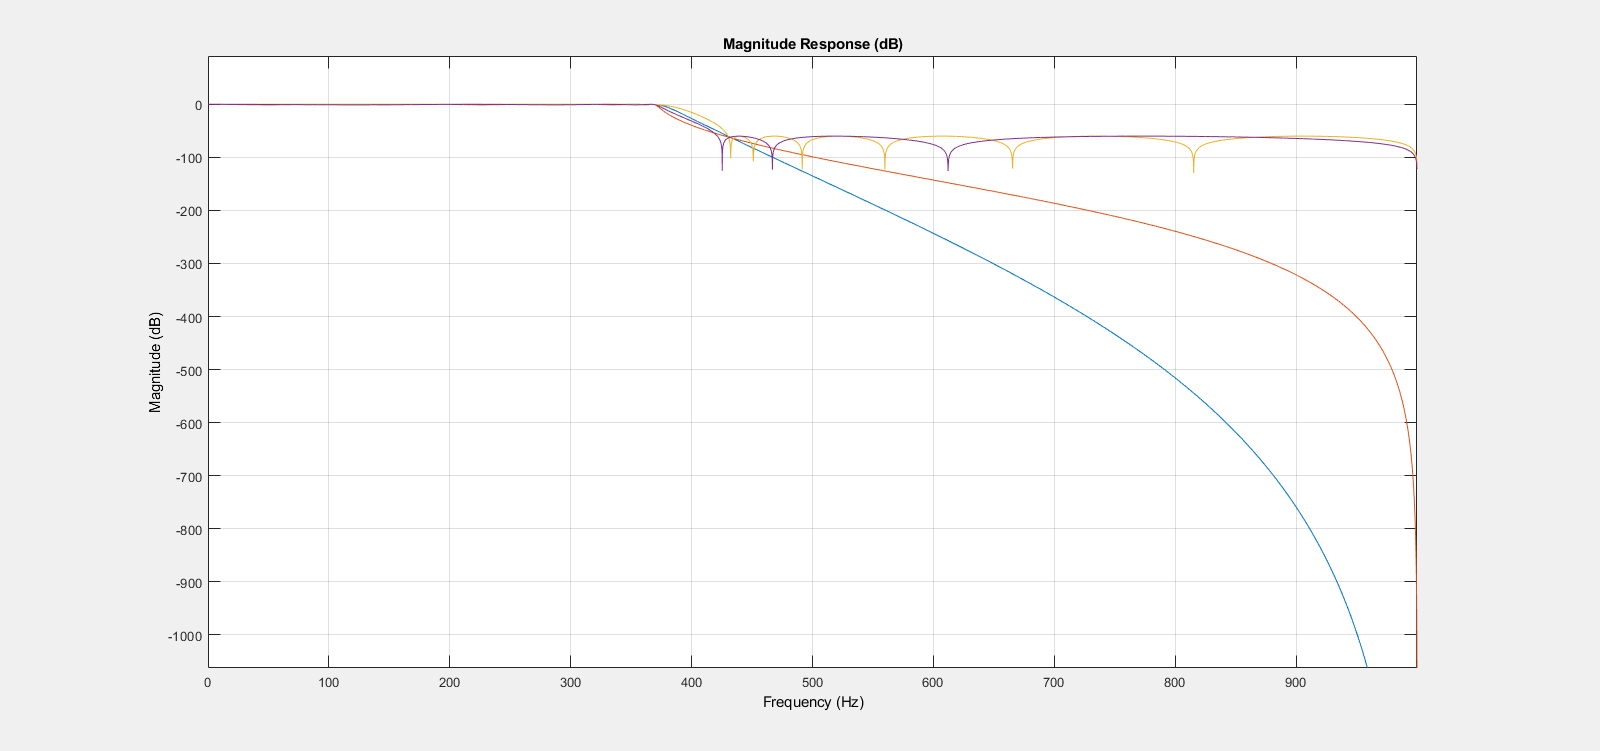

hfvt =   Figure (filtervisualizationtool) with properties:

      Number: 1
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 1600 751]
       Units: 'pixels'

  Use get to show all properties


Fpass = 370;
Fstop = 430;
Ap = 1;
Ast = 60;
Fsample = 2000;


dbutter = designfilt('lowpassiir',...
    "PassbandFrequency", Fpass, ...
    "StopbandFrequency" , Fstop,...
    "PassbandRipple" , Ap,...
    "StopbandAttenuation", Ast,...
    "SampleRate",Fsample,...
    "DesignMethod", "butter");

dcheby1 = designfilt('lowpassiir',...
    "PassbandFrequency", Fpass, ...
    "StopbandFrequency" , Fstop,...
    "PassbandRipple" , Ap,...
    "StopbandAttenuation", Ast,...
    "SampleRate",Fsample,...
    "DesignMethod", "cheby1");

dcheby2 = designfilt('lowpassiir',...
    "PassbandFrequency", Fpass, ...
    "StopbandFrequency" , Fstop,...
    "PassbandRipple" , Ap,...
    "StopbandAttenuation", Ast,...
    "SampleRate",Fsample,...
    "DesignMethod", "cheby2");

dellip = designfilt('lowpassiir',...
    "PassbandFrequency", Fpass, ...
    "StopbandFrequency" , Fstop,...
    "PassbandRipple" , Ap,...
    "StopbandAttenuation", Ast,...
    "SampleRate",Fsample,...
    "DesignMethod", "ellip");

hfvt = fvtool(dbutter, dcheby1, dcheby2, dellip)


Fs = 500; % Sample Rate = 500Hz
N = 500; % Number of samples we take
rng default;
n = (0: N-1) / Fs; % x(n) = x(nT)
x = cos(100 *2*pi* n) + 1 * randn(1,N)% Noise putting number in front can change the noise present

x =     1.5377    2.1429   -3.0679    0.0532    0.6278   -0.3077   -0.1246   -0.4664    2.7694    3.0785   -0.3499    3.3439   -0.0836   -0.8721    1.0238    0.7950    0.1849    0.6807    0.6000    1.7262    1.6715   -0.8985   -0.0918    0.8212    0.7979    2.0347    1.0359   -1.1125   -0.5151   -0.4783    1.8884   -0.8381   -1.8779   -1.6185   -2.6353    2.4384    0.6342   -1.5639    0.5613   -1.4025    0.8978    0.0676   -0.4898   -0.4962   -0.5559    0.9699    0.1441   -0.1813    0.2842    1.4183


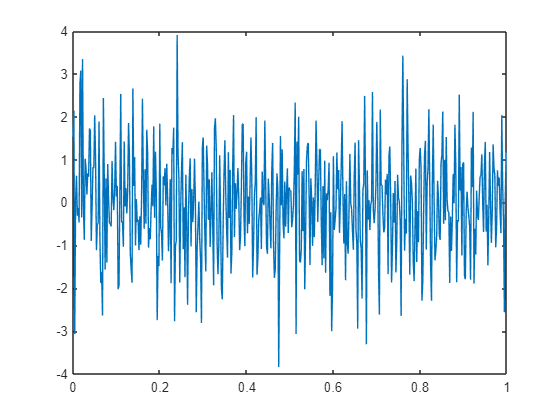

%100 Hz sine/cosine wave (Nyquiat frequency equation 500/2 = 250 being max freq
plot(n,x);

## Making Filter

% df = designfilt("lowpassfir",...
%     "FilterOrder", 100,...
%     "CutoffFrequency", 101,... %
%     "Samplerate", Fs);
% 
% y = filter(df,x);
% plot(n,y)

% Lagtime due to non linearity


% df = designfilt("lowpassfir",...
%     "FilterOrder", 100,...
%     "CutoffFrequency", 101,... %
%     "Samplerate", Fs);
% 
% D = mean(grpdelay(df))
% 
% y = filter(df,[x zeros(1,D)]);
% y = y(D+1:end); % Gets rid of first part from graph generated by lines 51 to 57
% plot(n,y);

%% Band Pass Filter

df = designfilt("bandpassfir",...
    "FilterOrder", 100,...
    "CutoffFrequency1", 99,... %
    "CutoffFrequency2", 101,...
    "Samplerate", Fs);

D = mean(grpdelay(df))

D = 50

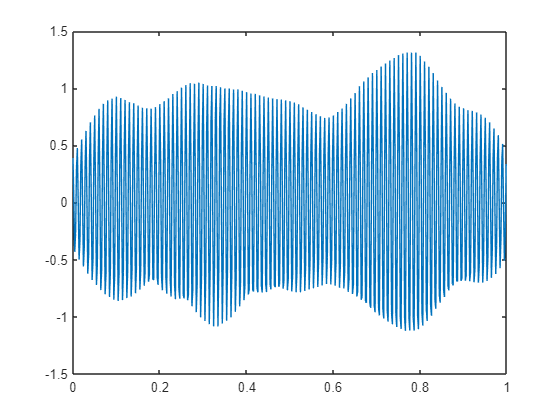


y = filter(df,[x zeros(1,D)]);
y = y(D+1:end); % Gets rid of first part from graph generated by lines 51 to 57
plot(n,y);

## Fourier Transform

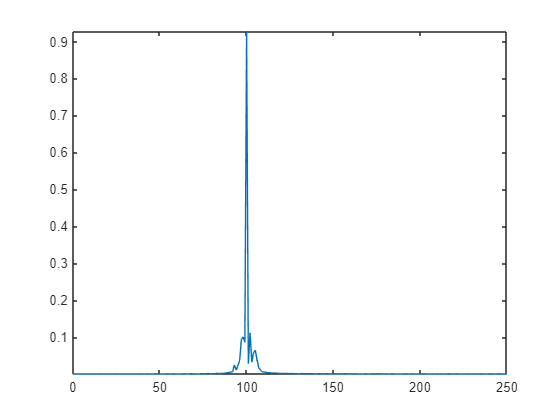

Y = fft(y); % 

% Algorithm to convert raw FFT to actual needed 
P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:N/2)/N;
plot(f,P1); axis tight;